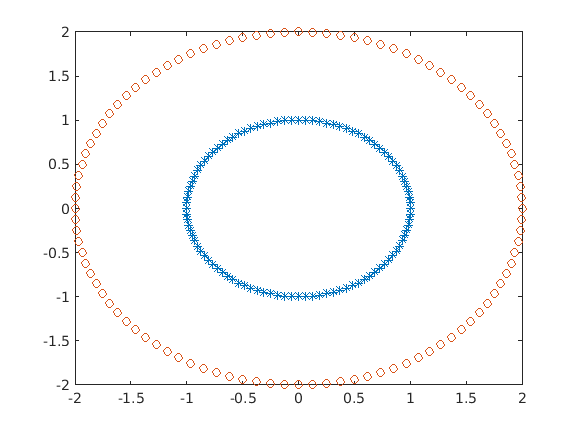

%Mapping to higher dimensional apace
%key idea behind so called 'kernel methods' and SVM
close all
 A=[1,1,1;-1 -1 -1]; % A don't play any role here
%It just tell 'plotregion' that we are dealing with 3D.
% b=[2;-2.01];% lb=-4 *ones(3,1);% ub=ones(3,1)*4;%A=[];
b=[]; lb=[]; ub=[];
N=100;	
theta=(0:N-1)*2*pi/N;
B1=[cos(theta);sin(theta)];
B2=[2*cos(theta);2*sin(theta)];
figure
plot(B1(1,:),B1(2,:),'*');
hold on
plot(B2(1,:),B2(2,:),'o');

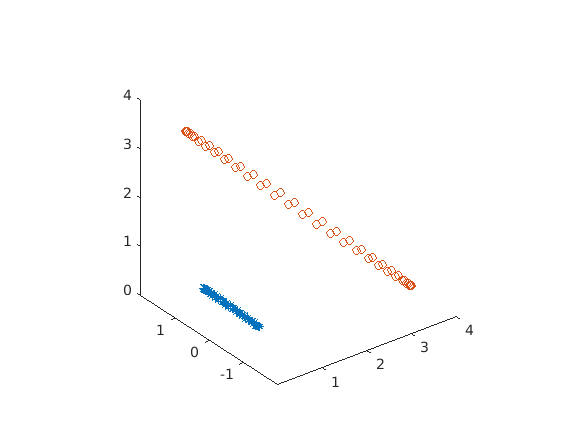

figure
% creating 3D data from 2D data
% Data-p0ints in B1 ad B2 are in columns.
%(x,y) is mapped to (x^2,y^2,xy)
C=B1.^2; % new first and second coordinates 
C=[C;(B1(1,:).*B1(2,:))];% appending third coordinate
plot3(C(1,:),C(3,:),C(2,:),'*');
hold on 
C=B2.^2;
C=[C;(B2(1,:).*B2(2,:))];
plot3(C(1,:),C(3,:),C(2,:),'o');
axis equal